# Finding a 4D SSM for an oscillator chain

This is an example of how to reconstruct a slow 4D SSM of a mechanical system using synthetic measurements of the full state space. In this example, we consider a damped oscillator chain with an additional nonlinear spring attached to the leftmost mass.

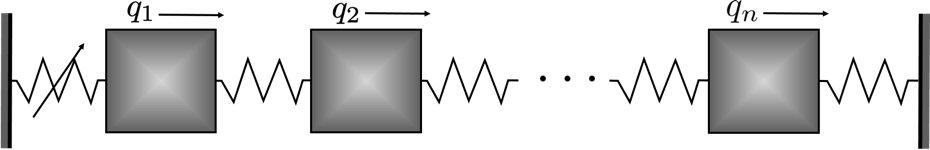

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) = \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $N\times N$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{y}} = \mathbf{A}\mathbf{y} + \mathbf{G}(\mathbf{y}) = \mathbf{F}(\mathbf{y})$$


with

$\mathbf{y}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0} 
& \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{y})=\left[\begin{array}{c} \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{y})\end{array}\right]$.

n         = 6;      % number of masses
mass      = 1;
stiffness = 1;
damping   = 0.03;

M = mass*eye(n);
K = stiffness*(2*eye(n) - diag(ones(1,n-1),-1) - diag(ones(1,n-1),1));
C = damping*(2*eye(n) - diag(ones(1,n-1),-1) - diag(ones(1,n-1),1));

% nonlinearities: f1 = 0.33*q1dot^2 + 2*q1^3 + 0.3*q1^2*q1dot^2 + 0.5*q1dot^3
F2 = sptensor(zeros(n, 2*n, 2*n));
F2(1,n+1,n+1) = 0.33;    % q1dot^2
F3 = sptensor(zeros(n, 2*n, 2*n, 2*n));
F3(1,1,1,1) = 2;         % q1^3
F3(1,1,1,n+1) = 0.3;     % q1^2*q1dot^2 
F3(1,n+1,n+1,n+1) = 0.5; % q1dot^3
fnl = {F2, F3};

[F, lambda] = functionFromTensors(M, C, K, fnl);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation.

nTraj = 4;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories. To this end we pick evenly spaced points in the phase space at a given distance from the origin. Thus all modes will be present at first. We expect the trajectories to eventually converge onto a slow 4D manifold, which will be identified and used to reduce the system dynamics.

ICRadius = 0.2;
IC = ICRadius * pickPointsOnHypersphere(nTraj, 2*n, 1);

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
tEnd = 500;
nSamp = 5000;
dt = tEnd/(nSamp-1);
tic
yData = integrateTrajectories(F, observable, tEnd, nSamp, nTraj, IC);

simulating trajectory 1 of 4...
simulating trajectory 2 of 4...
simulating trajectory 3 of 4...
simulating trajectory 4 of 4...


toc

Elapsed time is 1.780136 seconds.


## Data filtering

We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the middle mass displacement for one or several trajectories. In general, there may be many vibratory modes present at first, but the faster ones quickly die out. 

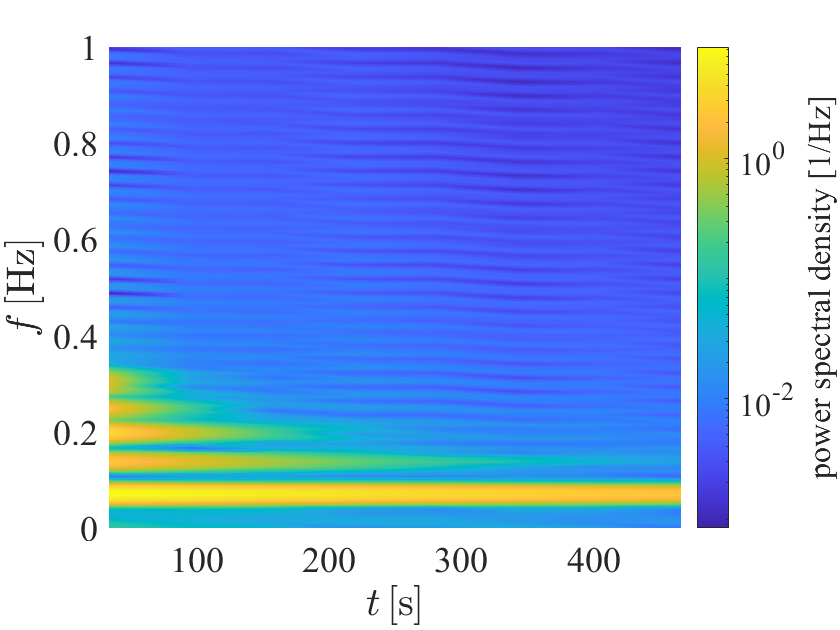

showSpectrogram(yData(indTrain(2),:), fix(n/2));
ylim([0,1])

Next, we use the information from the spectrogram to remove the first part of the training data. After the first few oscillations have passed, there are two dominant modes left in the frequency spectrum. We keep only the data in the time interval `sliceInt`. Based on the spectrogram, removal of the first 200 s would safely ensure trajectories on the 4D manifold, but we choose to keep some more of the data and initialize at 80 s. 

sliceInt = [80, tEnd];
yDataTrunc = sliceTrajectories(yData, sliceInt);
SSMDim = 4;

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

 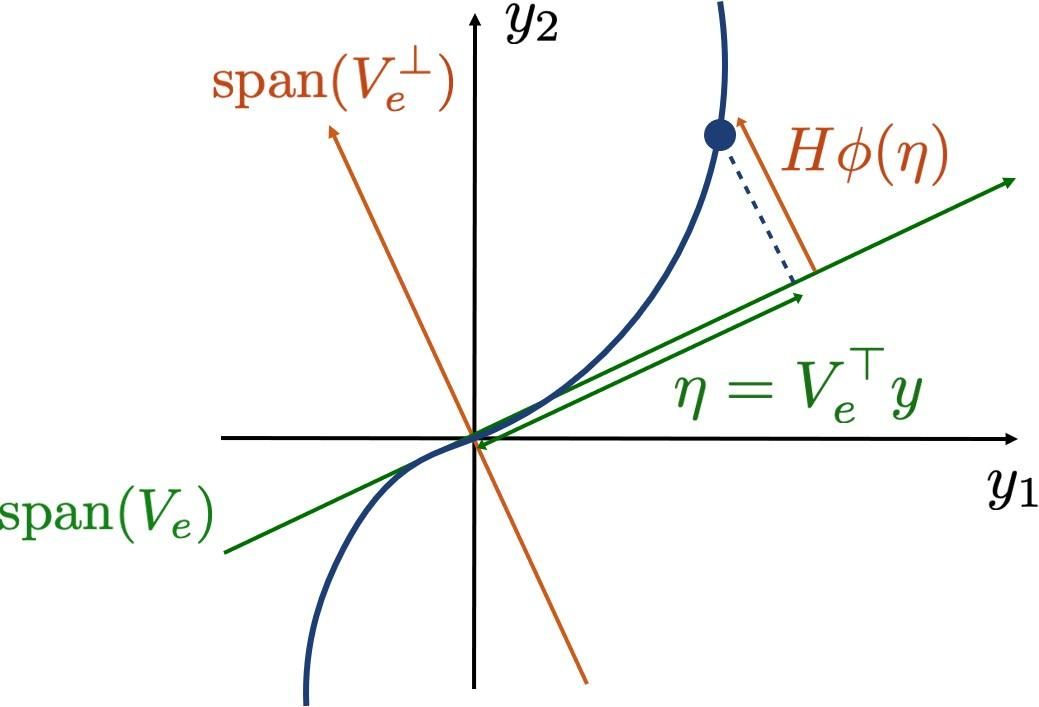

We seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab routine `fmincon` in `IMparametrization`.

SSMOrder = 3;
[V, SSMFunction, mfdInfo] = IMparametrization(yDataTrunc(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.416851e-06    2.220e-15    8.588e-10

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace. 

etaData = getProjectedTrajs(yData, V);
etaDataTrunc = getProjectedTrajs(yDataTrunc, V);

To visualize convergence onto the slow manifold after vibrations in the modes of larger damping die out, we plot the trajectories in modal coordinates. This is purely for demonstration, as typically the modes of the system are unknown a priori.

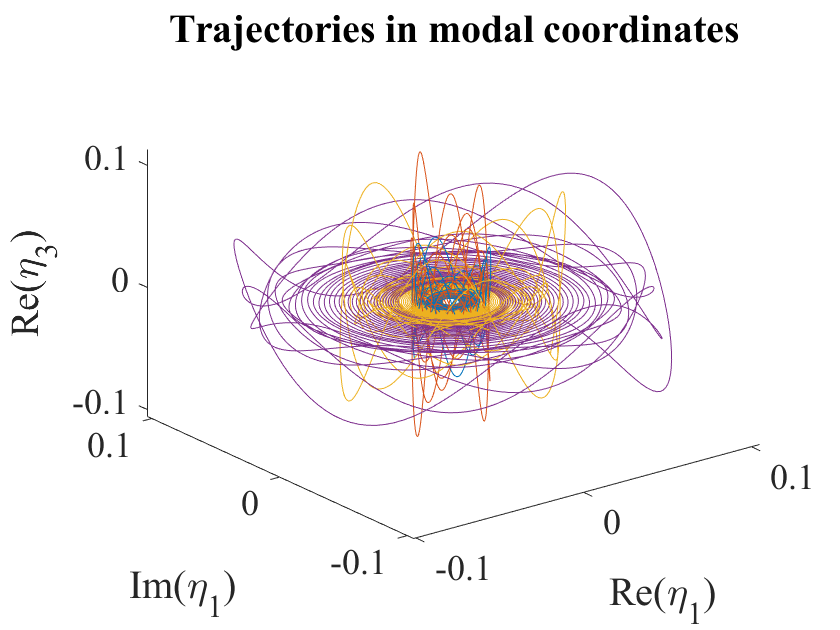

plotModes = [1,3];
plotModalTrajectories(yData, M, C, K, plotModes)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMdynamics_map` fits a polynomial map


$$\eta_{k+1} = W_r \phi(\eta_k)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the map $N$ will fulfill


$$z_{k+1} = N(z_k) \approx Dz_k + W_n\phi(z_k)$$


with $D$ a diagonal matrix and $W_n$ coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) \approx \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1       2.6942e-10                      1.05e-07
     1           5      2.61903e-10            820       4.25e-08  
     2           6      2.57966e-10              1       1.85e-08  
     3           7      2.55273e-10              1       3.19e-08  
     4           8      2.46739e-10              1       6.63e-08  
     5           9      2.39642e-10              1       6.12e-08  
     6          10      2.34821e-10              1       2.48e-08  
     7          11      2.32661e-10              1       1.35e-08  
     8          12      2.30688e-10              1       2.64e-08  
     9          13      2.28172e-10              1       3.68e-08  
    10          14       2.2552e-10              1       2.84e-08  
    11          15

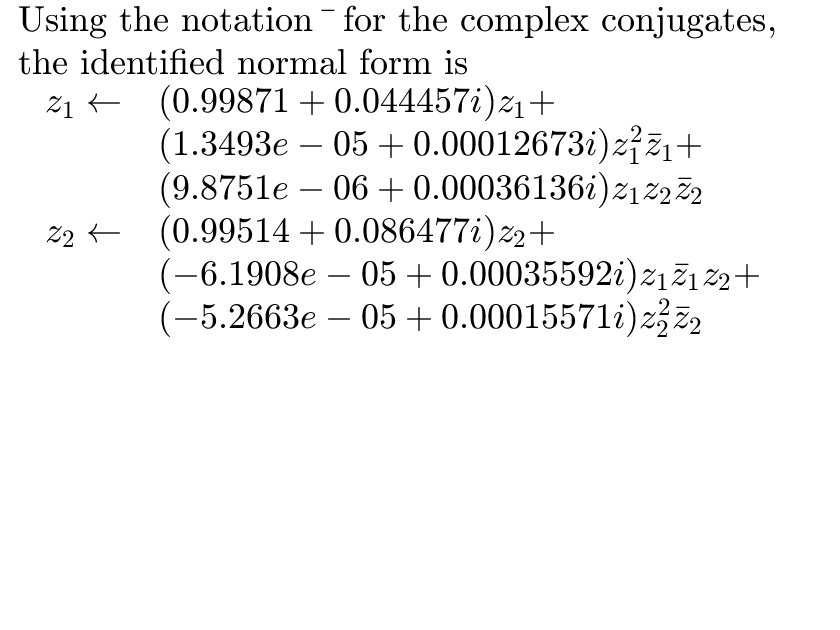

ROMOrder = 3;
[~,Tinv,N,T,NormalFormInfo] = IMdynamics_map(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and iterate our reduced order evolution rule to predict the development of the trajectory. 

zData = transformComplex(Tinv, etaDataTrunc);
[zRec, yRecNormal] = iterateMaps(N, zData, @(q) SSMFunction(T(q)));
etaRecNormal = transformComplex(T, zRec);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the measured one in the full state space.

[reducedTrajDist, fullTrajDist] = computeRecDynErrors(etaRecNormal, yRecNormal, etaDataTrunc, yDataTrunc);
RRMSE_normal = mean(fullTrajDist(indTest))

RRMSE_normal = 0.0393

We plot the first pair of reduced coordinates for the true test set trajectory in and compare it to the prediction. 

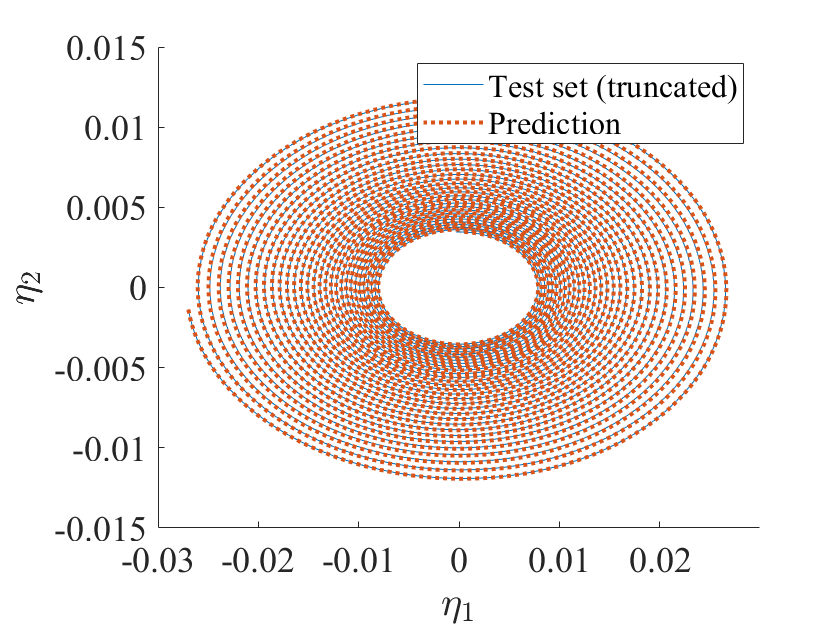

plotReducedCoords(etaDataTrunc(indTest(1),:), etaRecNormal(indTest(1),:))
legend({'Test set (truncated)', 'Prediction'})

We also plot the measured and predicted displacement for one of the masses. The reduced model seems to do well on previously unseen data, provided that it is initalized close to the manifold. We can do even better by increasing the manifold dimension.

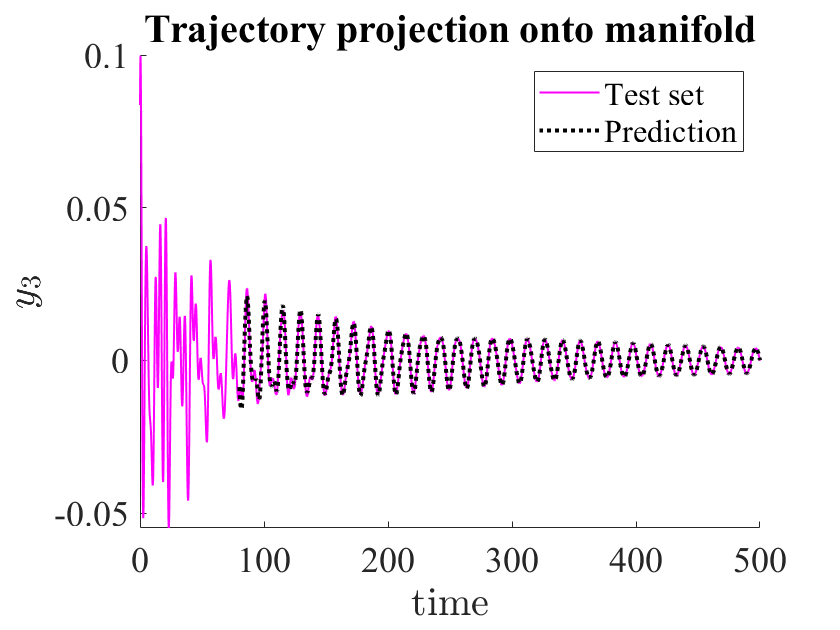

plotReconstructedTrajectory(yData(indTest(1),:), yRecNormal(indTest(1),:), fix(n/2), 'm')
legend({'Test set', 'Prediction'})

Finally we compare the estimated eigenvalues of the continuous evolution function to the ones computed with SSMTool. 

DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues =   -0.0030 - 0.4450i
  -0.0030 + 0.4450i
  -0.0113 - 0.8677i
  -0.0113 + 0.8677i


normalFormEigenvalues = computeEigenvaluesMap(NormalFormInfo, dt)

normalFormEigenvalues =   -0.0030 + 0.4448i
  -0.0030 - 0.4448i
  -0.0111 + 0.8666i
  -0.0111 - 0.8666i


## Backbone surfaces

With the knowledge of the coefficients of the normal form, we extract backbone surfaces for the instantaneous damping and frequency.

N_info = NormalFormInfo.N;
[damp,freq] = nonres_normalform(N_info.coeff,N_info.exponents, dt);

The data-driven polar normal form dynamics reads:

                        1                     r2_1                       r2_2          
                _________________    _______________________    _______________________

    Z_1(r) =    0.99871+0.044457i     1.3493e-05+0.00012673i     9.8751e-06+0.00036136i
    Z_2(r) =    0.99514+0.086477i    -6.1908e-05+0.00035592i    -5.2663e-05+0.00015571i

Notation: z_j = r_j*exp(1i*\theta_j) where r_j is the amplitude and \theta_j the phase; rk_j is the k-th power of r_j.
The polar form map consists of r_j <--| |Z_j(r)|r_j and \theta_j <--| \theta_j  + \arg(Z_j(r))


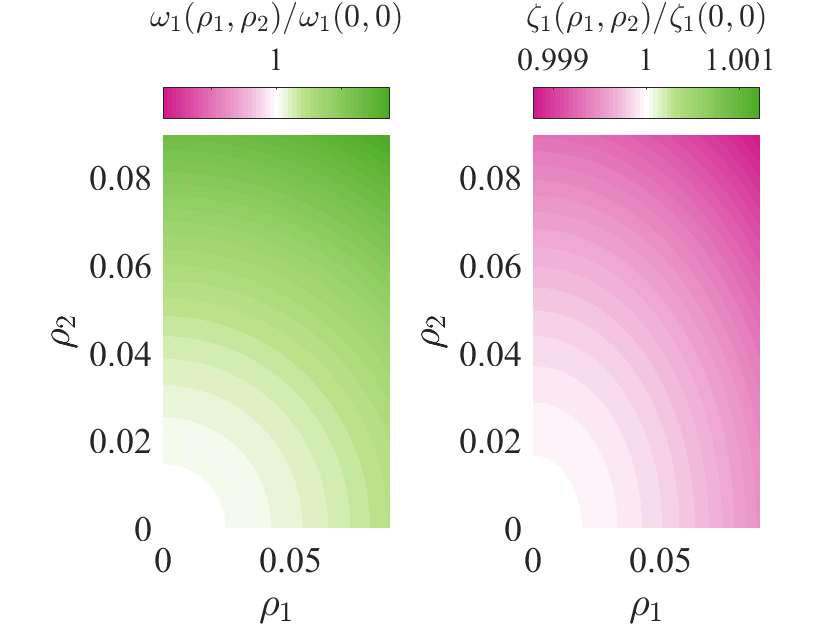

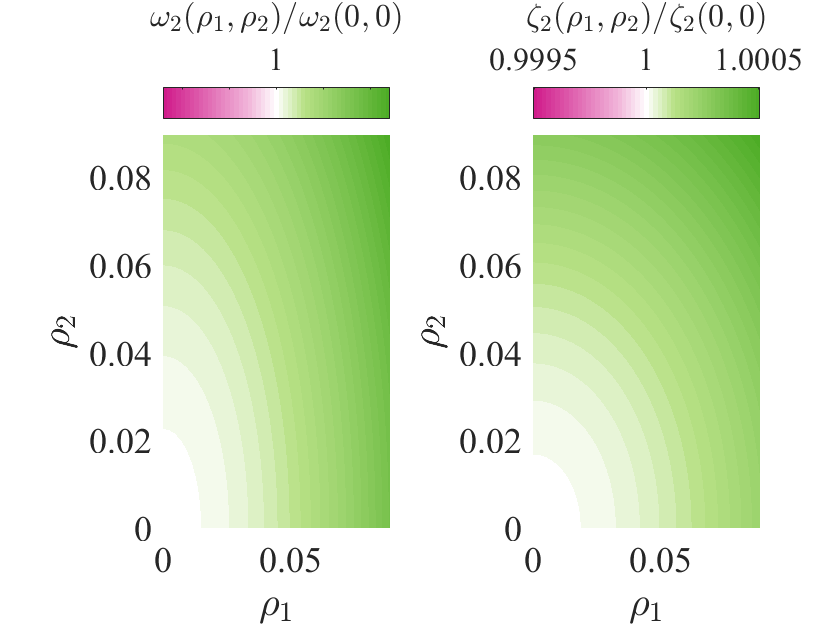

maxRho = abs(zData{indTest(1),2}(1,1));
if SSMDim == 2
    backbonecurves(damp, freq, SSMFunction, T, fix(n/2), maxRho, 'norm');
elseif SSMDim == 4
    maxRho2 = abs(zData{indTest(1),2}(3,1));
    backbonesurfaces(damp, freq, [maxRho, maxRho2], 'norm');
end